# Linear OLS Regression

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**MEconTools**](https://fanwangecon.github.io/MEconTools/)** Repositories**

## Fit a Line through Origin to Two Points

Fit a line from the origin through two points, given Equations $Y=a\cdot X$, where we have two pairs of points for x and y.

rng(3);
[x1, x2] = deal(rand(),rand());
[y1, y2] = deal(rand(),rand());
ar_x = [x1,x2]';
ar_y = [y1,y2]';

Fit a line through the two points, passing through the x-intercept. Three formulas that provide the same answer.

% simple formula
fl_slope_basic = (1/(x1*x1 + x2*x2))*(x1*y1 + x2*y2);
% (X'X)^(-1)(X'Y)
fl_slope_matrix = inv(ar_x'*ar_x)*(ar_x'*ar_y);
% Use matlab function
tb_slope_fitlm = fitlm(ar_x, ar_y, 'Intercept',false);
fl_slope_fitlm = tb_slope_fitlm.Coefficients{1, 1};

Visualize results.

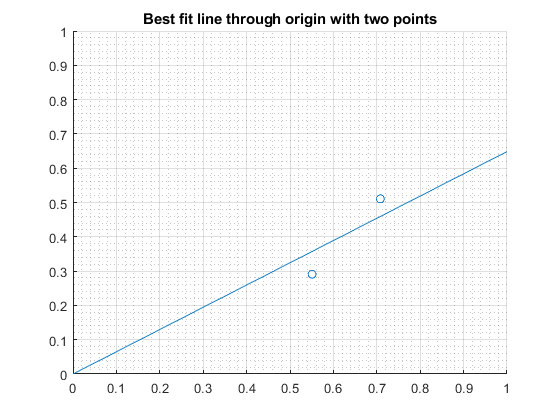

figure();
hold on;
scatter([x1,x2], [y1,y2]);
xlim([0, 1]);
ylim([0, 1]);
refline(fl_slope_basic, 0);
grid on;
grid minor;
title('Best fit line through origin with two points');

## Exactly Identify Three Linear Equations with Three Unknown Parameters

We have three "observations" equations with three unknown $\beta$ parameters, Generate the true $y$ value based on random right-hand-side matrix and true $\beta$, and estimate/solve for $\beta$ given "data" on $y$ and $x$ matrix. 

First generate the data.

% Generate a 3 by 3 matrix of random values
rng(3);
it_row_n = 3;
it_col_n = 3;
mt_rhs = rand([it_row_n, it_col_n]);

% Generate true coefficients
ar_beta_true = rand([it_row_n, 1]);

% Generate LHS, given true parameter
ar_lhs = mt_rhs*ar_beta_true;

Second, the estimating/exact-fit equation and estimated/solved $\beta$. 

% OLS regression function
fc_ols_lin = @(y, x) (x'*x)^(-1)*(x'*y);

% Estimate
ar_beta_esti = fc_ols_lin(ar_lhs, mt_rhs);

% Display
tb_beta = array2table([ar_beta_true, ar_beta_esti]);
cl_col_names = ["beta true", "beta estimates"];
cl_row_names = strcat('row_coef_', string((1:it_row_n)));
tb_beta.Properties.VariableNames = matlab.lang.makeValidName(cl_col_names);
tb_beta.Properties.RowNames = matlab.lang.makeValidName(cl_row_names);
disp(tb_beta);

                  betaTrue    betaEstimates
                  ________    _____________

    row_coef_1     0.44081       0.44081   
    row_coef_2    0.029876      0.029876   
    row_coef_3     0.45683       0.45683   

